## Práctica Lab 4 – Simulación de Sistemas de Control (MATLAB + Simulink)

Curso: Sistemas de Control ContinuoObjetivo

- Preparar variables en MATLAB

- Ejecutar un modelo de Simulink desde MATLAB

- Exportar y analizar resultados

**Nota técnica:**

Al guardar un modelo se genera un archivo `.slx` que contiene el diagrama y la configuración de los bloques.4.1) Procedimiento de arranque

- Ejecutar `simulink` en MATLAB

- Abrir **New > Blank Model**

- Explorar el **Library Browser**

- Identificar librerías clave:

- **Simulink:** Commonly Used Blocks, Continuous, Discrete, Sinks, Sources, Math Operations, Signal Routing

- **Control System Toolbox**

- **Simulink Extras** (si está disponible)

Principales sublibrerías

**Simulink:**

- *Commonly Used Blocks:* Sum, Gain, Integrator, Derivative, Step, Constant, Mux, Demux, Scope

- *Continuous:* Integrator, Transfer Fcn, State-Space, Zero-Pole, PID Controller

- *Discrete:* Integrador y funciones discretas

- *Sinks:* Scope, To Workspace, Display, Floating Scope

- *Sources:* Step, Ramp, Sine Wave, Pulse Generator, Constant, Clock, From Workspace

- *Math Operations:* Add, Multiply, Divide, Math Function

- *Signal Routing:* Mux, Demux, Switch

**Control System Toolbox:**

- Diseño clásico: PID, Transfer Function, State-Space

- Sistemas lineales

- Control avanzado: adaptativo, robusto, optimización

**Simulink Extras (opcional):**

- Bloques adicionales (Discrete, Sinks, Sources)

## 4.2) Construcción del modelo (ejemplo1)

Objetivo: Sistema de Control Retroalimentado

- Proceso: doble integrador (2 bloques Integrator en cascada)

- Controlador: compensador PD

**Pasos:**

- Crear modelo en blanco

- Implementar el diagrama de la guía

- Agregar **Floating Scope** (buscándolo en el Library Browser)

- Guardar como `ejemplo1`

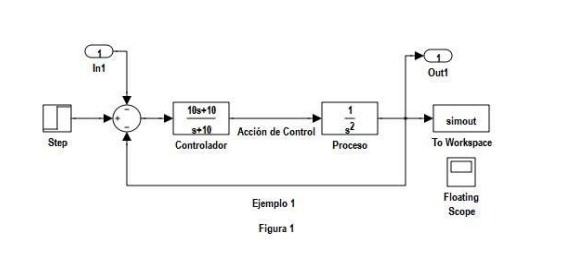

## 4.3) Scope, Logging y visualización

- Abrir el **Floating Scope**

- Ir a: *View > Configuration Properties*

- Activar **Logging** al workspace

**Formatos de guardado:**

- Array

- Structure

- Structure with time

**Conexión sugerida:**

Entrada / Salida / Control → Mux → Scope4.4) Bloques In1, Out1 y To Workspace

` Conexion sugerida:`

` [entrada] ``----``\`

` [salida ] ``-----` `>` `Mux`` (``3``) ``-->`` Scope`

` [control] ``----/`

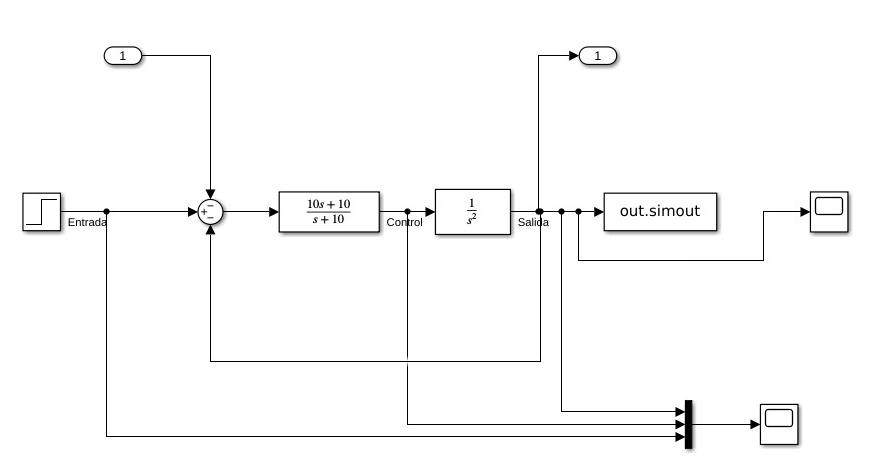

## 4.4) **Outport** y **To Workspace**

- Abrir y revisar parámetros de **In1**, **Out1** y **To Workspace**

**Funciones:**

- **In1 (Inport):** entrada al modelo

- **Out1 (Outport):** salida del modelo

- **To Workspace:** guarda señales para análisis

**Diferencia clave:**

- **Outport:** define la salida formal del modelo (interfaz y comunicación con `sim`)

- **To Workspace:** solo registra datos en el workspace (array o estructuras)

**Conclusiones:**

- Usar **Outport** para exportar señales del modelo

- Usar **To Workspace** para análisis posterior

- Ambos pueden coexistir

**Resumen:**

- Outport = salida formal

- To Workspace = almacenamiento para análisis

## 4.5) Parametrización y simulación

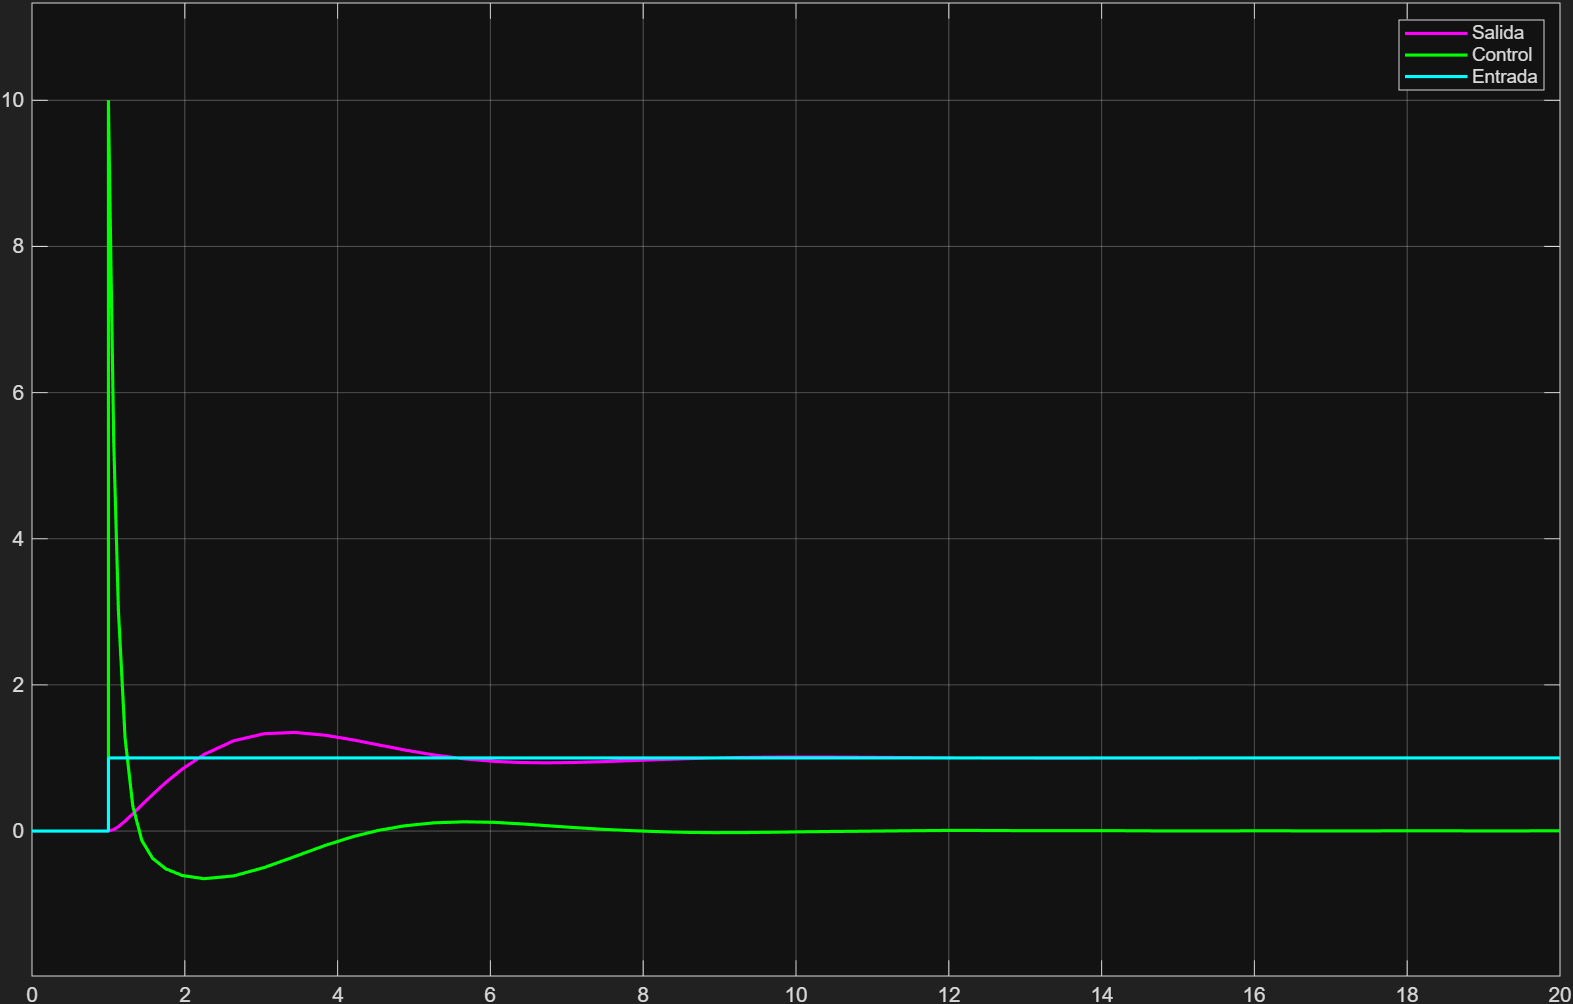

Configurar en:

**Modeling > Model Settings**

**Opciones principales:**

- **Solver**

- Tipo de paso (fijo o variable)

- Método numérico

- Tiempo de simulación

- **Data Import/Export**

- Entrada desde workspace (In1)

- Salida al workspace (Out1 o global)

- Guardar: `time`, `states`, `output`

- Formato recomendado: **Array**

## Variables generadas en el workspace (ETML)

Al ejecutar `sim(...)` se obtienen:

- **tout:** vector de tiempo

- **xout, yout:** señales de salida (Outport)

- **simout:** datos del Scope

- **SimulationMetadata:** información completa de la simulación

- **ErrorMessage:** mensajes de error (vacío si no hay fallos)

**Notas:**

- Usar `whos` para visualizar variables

- Analizar con `plot()`

- Los nombres y formatos pueden configurarse en:*Model Settings > Data Import/Export*

- `SimulationMetadata y ErrorMessage NO`` son variables inesperadas o problematicas.`

- ` Son INDICADORES DE EXITO de la simulacion. Su presencia confirma que:`

-  `1.` `sim``(...) se ejecuto correctamente`

-  `2.`` No hubo errores en la ejecucion`

-  `3.`` Toda la informacion de la corrida fue registrada para auditoria`

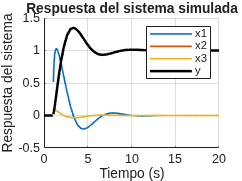

% Extraer tiempo
t = out.tout;

% Extraer estados
x1 = out.xout(:,1);
x2 = out.xout(:,2);
x3 = out.xout(:,3);

% Extraer salida
yData = out.yout(:,1);   % si yout es vector, tambien sirve

% Graficar
figure
hold on
plot(t, x1, 'LineWidth', 1.2)
plot(t, x2, 'LineWidth', 1.2)
plot(t, x3, 'LineWidth', 1.2)
plot(t, yData, 'k', 'LineWidth', 1.8)

xlabel('Tiempo (s)')
ylabel('Respuesta del sistema')
title('Respuesta del sistema simulada')
legend('x1','x2','x3','y')
grid on

hold off